%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%                                                %%%%%%%%
%%%%%%%%             Seyyed Erfan Mohammadi             %%%%%%%%
%%%%%%%%                  Topic : ERP                   %%%%%%%%
%%%%%%%%                                                %%%%%%%%
%%%%%%%%                                                %%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Load in EEG data and make time vector.

clear ;
close all;
clc;

load eeglab_data.mat;
time=-200:5:1000;

### Average re-referencing.

average_channels=mean(data,1);
data_rereference=data-average_channels;

### Find event.

event_index=zeros(30,4);
event_timepoint=zeros(30,4);
epoch=cell(1,4);

event_sample=cell2mat(struct2cell(event));
event_sample=squeeze(event_sample(1,:,:));

% I use latency row of event data
event_time=cell2mat(struct2cell(event));
event_time=squeeze(event_time(2,:,:));

event_class=unique(event_sample);

### Epoching between -200 to 1000 ms.

event_class_target=event_class(1:4);
for i=1:size(event_timepoint,2)
    event_index(:,i)=find(event_sample==event_class_target(i));
    event_timepoint(:,i)=event_time(event_index(:,i));
    for j=1:size(event_timepoint,1)

        epoch{i}(:,:,j)=data_rereference(:,(event_timepoint(j,i)-40:event_timepoint(j,i)+200));
        %200 samples after events is my epoch(see next section)
        % 50 samples befor events is my baseline.
        % total 250 samples (1 second)
        epoch{i}(:,:,j)=epoch{i}(:,:,j)-mean(epoch{i}(:,1:50,j),2); %Baseline corraction
    end
end

### Which channle do you want to plot "all epochs"?

which_stimulus=1; % 111  112  121  122
which_channle=30;  % you can change it!

### ERP.

ERP=cell(1,4);
for i=1:size(event_timepoint,2)
    ERP{i}=mean(epoch{i},3);
end

### Plot all ERP per channel.

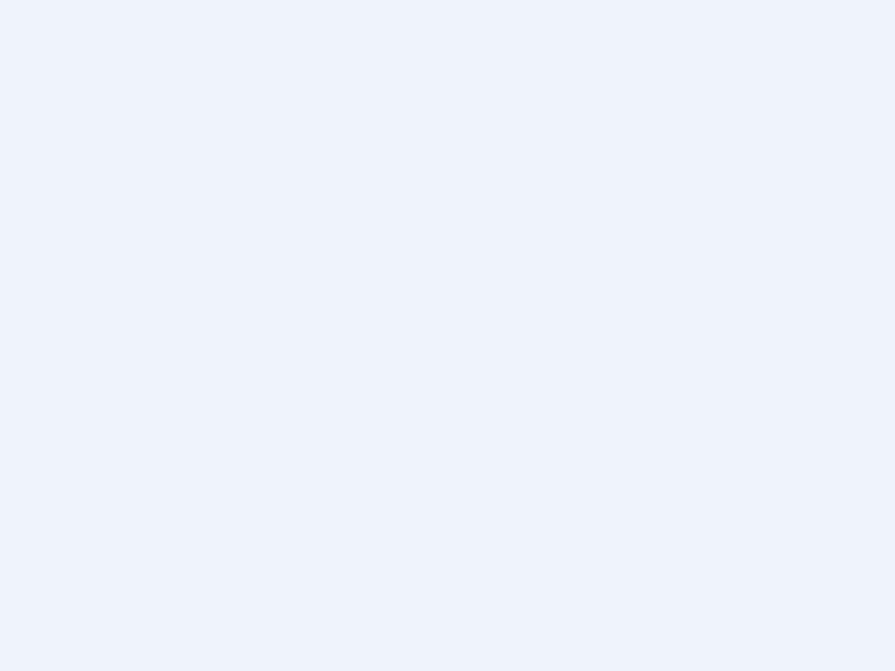

for j=1:size(event_timepoint,1)
    hold off;
    subplot(5,6,j);
    plot(time,ERP{which_stimulus}(j,:));
    title([ 'Channle= ' num2str(j) ]);
end
sgtitle(['ERPs per channel' ' (Event '...
    num2str(event_class(which_stimulus)) ')']);

### ERP image.

clf;
imagesc(time,flip(1:size(epoch,3)),-squeeze(epoch{which_stimulus}(which_channle,:,:))');
colorbar;
sgtitle(['ERP image (Channel ' num2str(which_channle) ')' ' (Event ' ...
    num2str(event_class(which_stimulus)) ')'])
set(gca,'clim',[-150 300])

### Plot all epochs per channle.

clf;
plot(time,squeeze(epoch{which_stimulus}(which_channle,:,:)));
sgtitle(['Epochs per channel (Channel ' num2str(which_channle) ')' ' (Event ' ...
    num2str(event_class(which_stimulus)) ')'])
xlabel('Time')
ylabel('mV')

### ERPs in one plot.

clf;
plot(time,ERP{which_stimulus});
sgtitle(['ERP of channels' ' (Event ' ...
    num2str(event_class(which_stimulus)) ')']);
xlabel('Time')
ylabel('mV')

### GFP.

clf;
gfp = std(ERP{which_stimulus});
varians=var(ERP{which_stimulus});
plot(time, varians ,'k');
hold on;
plot(time, gfp);
xlabel('Time')
sgtitle(['GFP and topographic variance' ' (Event ' ...
    num2str(event_class(which_stimulus)) ')']);

### ERPs of events.

clf;
for j=1:size(event_timepoint,2)
    plot(time,ERP{j}(which_channle,:));
    hold on
end
sgtitle(['ERP of events ' '(Channel ' num2str(which_channle)  ')']);
xlabel('Time')
ylabel('mV')
legend('event 111','event 112','event 121','event 122', 'Location','northwest');

### Topoplot of ERPs.

clf;
for i=1:16
    subplot(4,4,i);
    topoplot(-ERP{which_stimulus}(:,((i*8)+37)),chanlocs);
    %I use (i+5)*10) for skip pre-stimulus samples.
    % I use - for invers color of plot!
    title([ 'Time= +' num2str(time((i*8)+37))]);
end
sgtitle('topoplot of ERPs')